# ELEC-8103 – Modelling, Estimation, and Dynamic Systems

# Assignment 3

# Deadline: **15.10.2023 at 23:59**

# **Problem 1 (1.25 points)**

- **Piezo stack actuators**** are used as linear electromechanical drives or motors. They act mainly as an expanding element generating a compressive force.**

- **We have a piezoelectric actuator in the lab, but its specifications are unknown. We are interested in ****the actuator gain**** (**$\mathit{\mathbf{G}}$**), which is the ratio of the resulting linear displacement of the actuator to the applied electrical voltage.**

- **We have prepared a testing setup shown in Fig. 1. Using the setup, we send a signal from a PC through an AD/DA board and an amplifier to the actuator and measure the resulting displacement of the actuator with a laser sensor.**

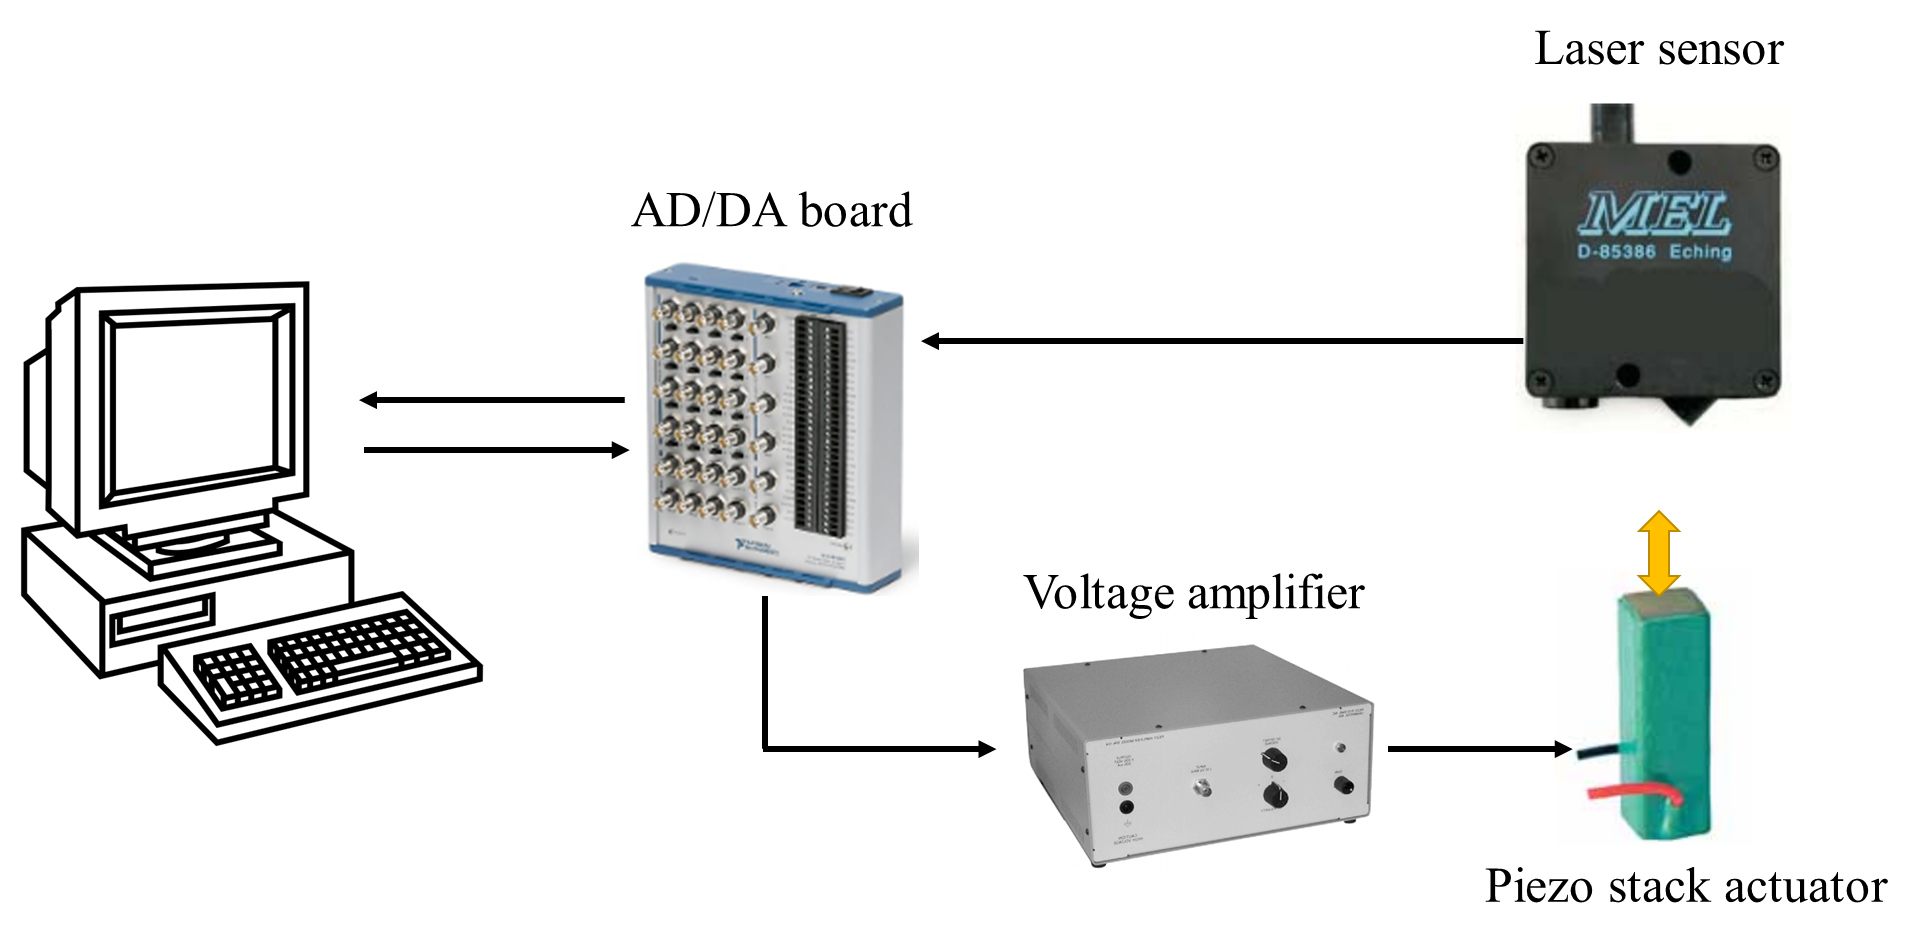`

**Figure 1** – Schematic of the testing setup.

- **The task is to estimate the actuator gain **$\mathit{\mathbf{G}}$** using the following equation:**

### 
$$\mathit{\mathbf{d}}=\mathit{\mathbf{G}}\cdot \mathit{\mathbf{v}}$$


- **In this equation, **$\mathit{\mathbf{v}}$** is the applied voltage and **$\mathit{\mathbf{d}}$** is the displacement of the actuator. **

- **To estimate **$\mathit{\mathbf{G}}$**, we excite the actuator with known voltage **$\mathit{\mathbf{v}}$** and measure the resulting displacement **$\mathit{\mathbf{d}}$ **with the laser sensor.**

- **Load the datafile:** In the script below, load the “data1.mat” datafile. This file contains applied voltages $\mathit{\mathbf{v}}$ (in Volts) and the measured resulting displacements $\mathit{\mathbf{d}}$ (in μm).

- **Estimate:** Use the provided data and the above-mentioned equation to estimate $\mathit{\mathbf{G}}$.

- **Plot the data points and fitted function: **Plot the data points $\left(\mathit{\mathbf{v}},\mathit{\mathbf{d}}\right)$. On the same figure, plot the fitted function, $\mathit{\mathbf{d}}=\mathit{\mathbf{G}}\cdot \mathit{\mathbf{v}}$, for $\mathit{\mathbf{v}}$ within the range [0,100] Volts.

- **Predict:** Predict the value of $\mathit{\mathbf{d}}$ when $\mathit{\mathbf{v}}$ = 75 Volts.

**Hints****: **

- For estimation and prediction, you may use either MATLAB’s Curve Fitting Toolbox or the functions [**polyfit**](https://se.mathworks.com/help/matlab/ref/polyfit.html) and [**polyval**](https://se.mathworks.com/help/matlab/ref/polyval.html).

- If you decide to use Curve Fitting Toolbox, save the Toolbox-generated code in a separate script named "createFit1.m" and call it from the script below to estimate $\mathit{\mathbf{G}}$.

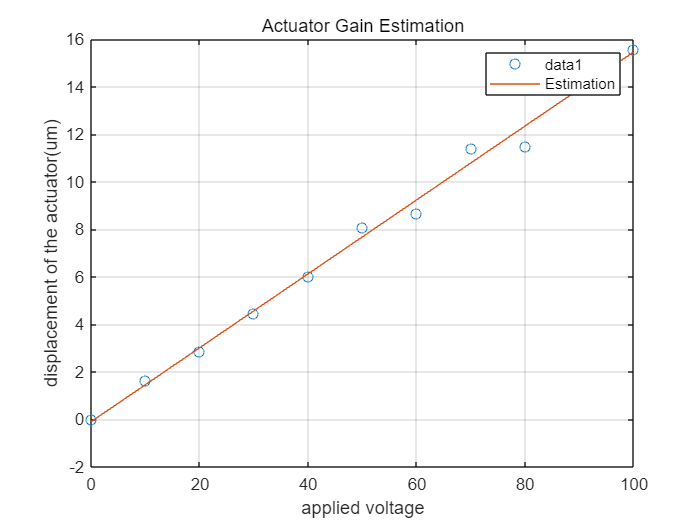

clear

load('data1.mat'); % Load the datafile

%---------------------------------------------------------------
p = polyfit(v,d,1);

v_t = 0:10:100;

p1 = polyval(p, v_t);

figure;
plot(v, d, 'o', v_t, p1, '-');
xlabel('applied voltage');
ylabel('displacement of the actuator(um)');
legend('data1', 'Estimation');
title('Actuator Gain Estimation');
grid on;


% Predict the value of Displacement at 75 Volts
f1 = polyval(p, 75);
disp(['Predicted Displacement at 75 Volts: ', num2str(f1), ' μm']);

Predicted Displacement at 75 Volts: 11.5731 μm


# **Problem 2 (3 points)**

- **Particle Tracking Velocimetry (PTV) is used to model the particle motion in field-based manipulation techniques.**

- **PTV employs a camera to track positions of particles frame by frame, compiling a dataset of initial positions and subsequent displacements of the particles.**

- **Figure 2A illustrates the application of PTV to a vibrating plate, enabling the collection of a training dataset of particle motion.**

- **The dataset includes training inputs, (**$\mathit{\mathbf{x}}$**, **$\mathit{\mathbf{y}}$**), representing the ****initial positions**** of particles, and training outputs, (**$\mathit{\mathbf{u}}$**, **$\mathit{\mathbf{v}}$**), representing their ****corresponding displacements in the X- and Y-directions**** (see Fig. 2B).**

- **The task is to model the particle displacements (**$\mathit{\mathbf{u}}$**, **$\mathit{\mathbf{v}}$**) as functions of the initial positions (**$\mathit{\mathbf{x}}$**, **$\mathit{\mathbf{y}}$**).**

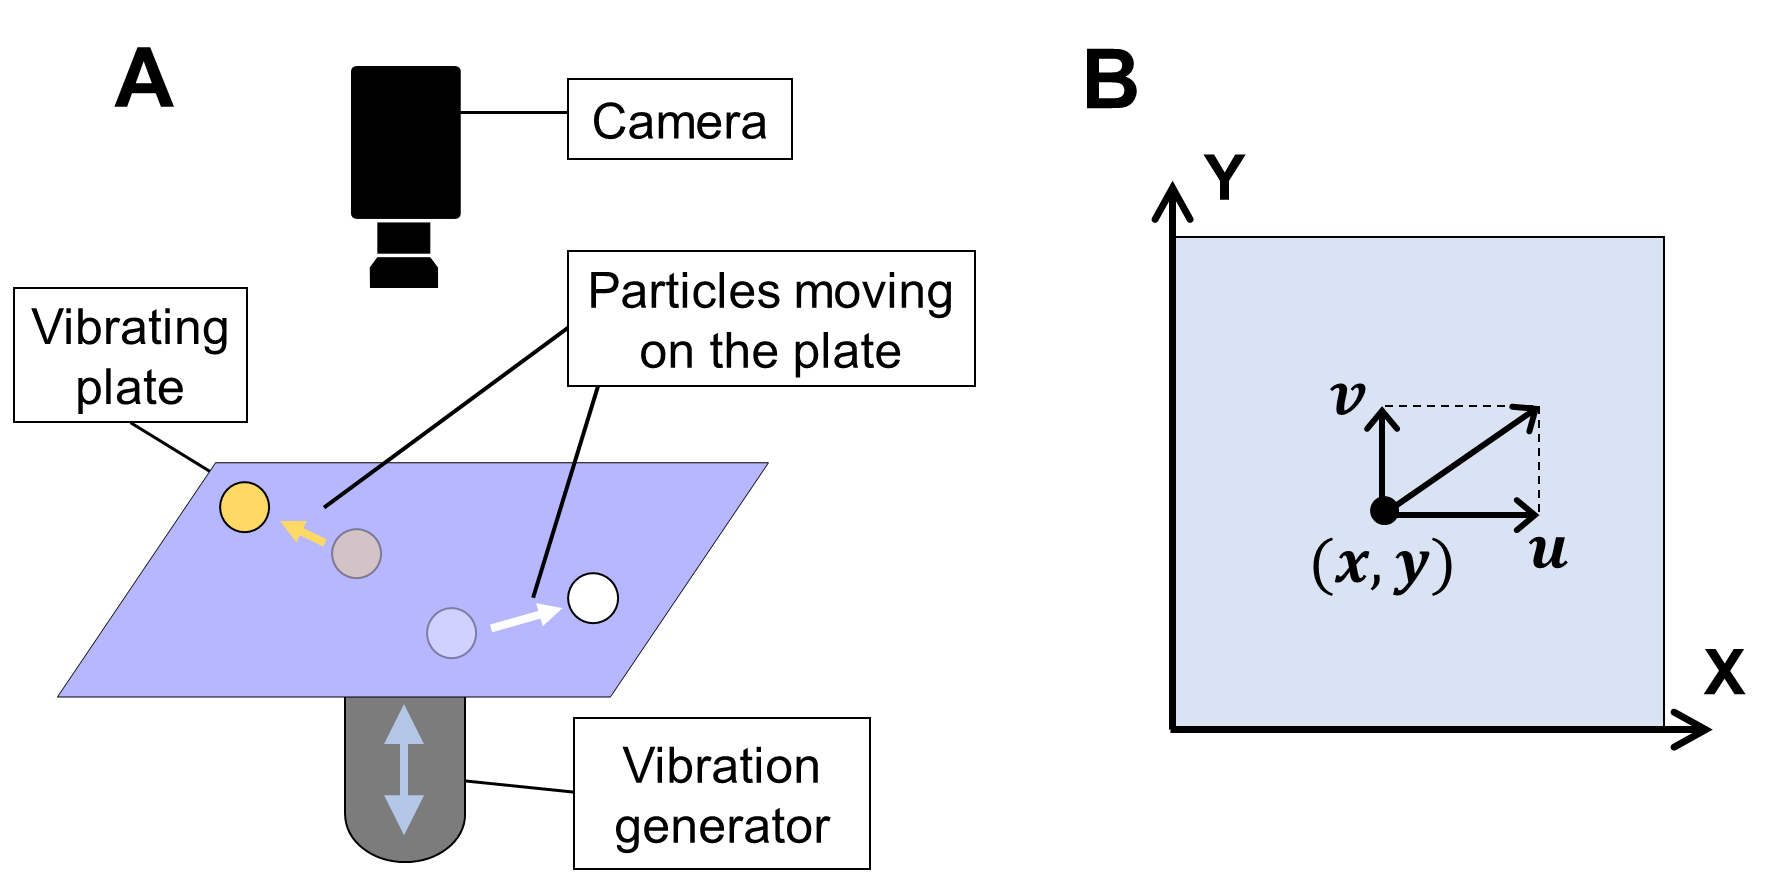

**Figure 2.** (**A**) PTV applied to a vibrating plate. (**B**) Particle motion on the plate: $\mathit{\mathbf{u}}$ and $\mathit{\mathbf{v}}$ are displacement components of a particle as functions of its initial position ($\mathit{\mathbf{x}}$**, **$\mathit{\mathbf{y}}$).

- **Load the datafile: **In the script below, load the “data2.mat” datafile. The file contains training inputs, $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{y}}$, and training outputs, $\mathit{\mathbf{u}}$ and $\mathit{\mathbf{v}}$.

- **Fit: **Use MATLAB’s Curve Fitting Toolbox to fit polynomial surfaces $\mathit{\mathbf{f}}$ and $\mathit{\mathbf{g}}$ to the data. In the toolbox, presume 2nd-order polynomials for both fitted functions, $\mathit{\mathbf{u}}=\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)$ and $\mathit{\mathbf{v}}=\mathit{\mathbf{g}}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)$. Save the Toolbox-generated code in a separate script, named "createFit2.m". **(1.5 points)**

- **Predict: **For $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{y}}$ in the grid space [0,1] (see the code below), predict values of $\mathit{\mathbf{u}}$ and $\mathit{\mathbf{v}}$. **(0.75 points)**

- **Visualize: **Use a [**quiver plot**](https://se.mathworks.com/help/matlab/ref/quiver.html) to visualize the predictions. **(0.75 points)**

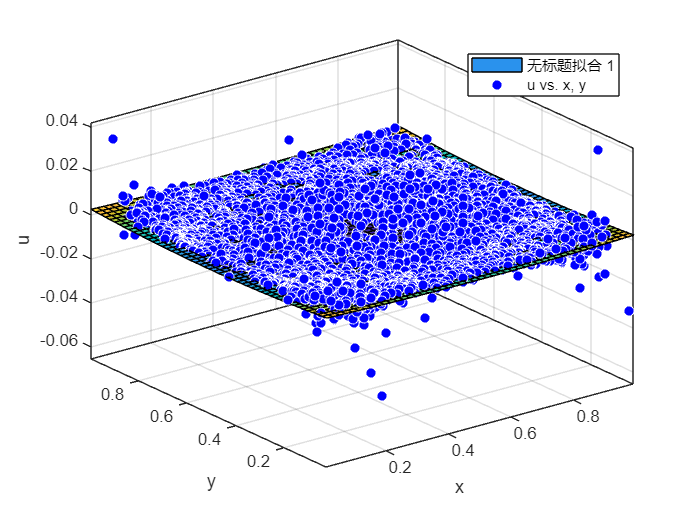

     线性模型 Poly22:
     fitresult_u(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2
     系数(置信边界为 95%):
       p00 =    0.002346  (0.001888, 0.002805)
       p10 =   -0.005424  (-0.00679, -0.004058)
       p01 =    -0.01008  (-0.01145, -0.00871)
       p20 =     0.00537  (0.004126, 0.006614)
       p11 =   0.0003264  (-0.0007682, 0.001421)
       p02 =     0.01009  (0.00885, 0.01133)



clear

load('data2.mat'); % Load the datafile

[gridx,gridy] = meshgrid(0:0.05:1,0:0.05:1); % Grid space of x and y for predicting u and v

%---------------------------------------------------------------
[fitresult_u, ~] = createFit2(x, y, u)

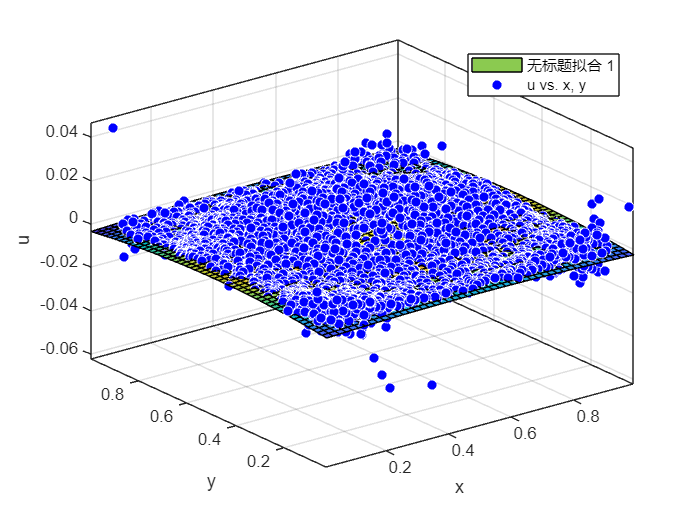

     线性模型 Poly22:
     fitresult_v(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2
     系数(置信边界为 95%):
       p00 =   -0.003262  (-0.00374, -0.002784)
       p10 =    0.006574  (0.005152, 0.007995)
       p01 =     0.01621  (0.01479, 0.01764)
       p20 =   -0.006599  (-0.007894, -0.005305)
       p11 =  -3.394e-05  (-0.001173, 0.001105)
       p02 =    -0.01679  (-0.01808, -0.0155)



gof = 包含以下字段的 struct :
           sse: 0.0789
       rsquare: 0.1012
           dfe: 6829
    adjrsquare: 0.1006
          rmse: 0.0034


predicted_u = fitresult_u(gridx, gridy);

[fitresult_v, gof] = createFit2(x, y, v)

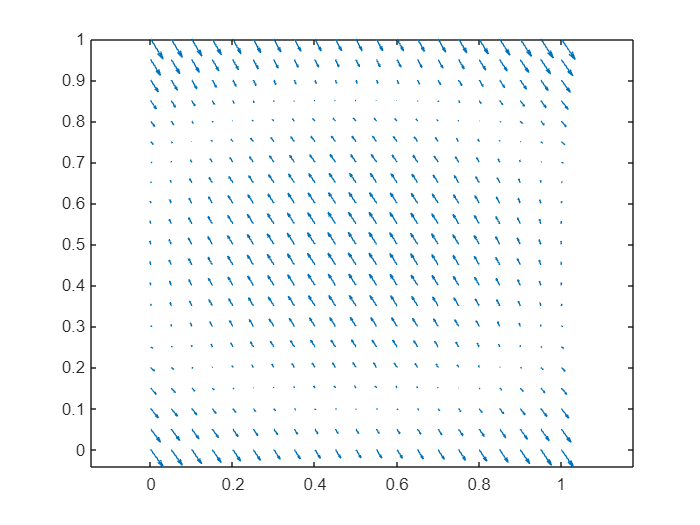

predicted_v = fitresult_v( gridx, gridy);

quiver(gridx,gridy,predicted_u,predicted_v);
axis equal

# **Problem 3 (3.25 points)**

- **Load the datafile: **In the script below, load the “data3.mat” datafile. The file contains training inputs **x** and outputs **y**, and validation inputs and **xv** and outputs **yv**.

- **Estimate: **Using the training data and the closed-form solution, estimate the parameters $k_i$ of the following function:

## 
$$y=k_1 x^{k_2 }$$


              Note that you are not allowed to use MATLAB’s Curve Fitting Toolbox for this task. **(1.25 points)**

          3. **Visualize: **Make a [**scatter plot**](https://se.mathworks.com/help/matlab/ref/scatter.html) of the (**x**, **y**) and (**xv**, **yv**) data. On the same figure, plot the estimated function for **x** within the range [0,15]. **(0.5 points)**

          4. **Goodness of fit**: Compute the Sum of Squared Errors (SSE) and the coefficient of determination ($R^2$) for the training data. Additionally, calculate the SSE for the validation data. **(0.5 points)**

          5. **Alternative models: **Use functions [**polyfit**](https://se.mathworks.com/help/matlab/ref/polyfit.html) and [**polyval**](https://se.mathworks.com/help/matlab/ref/polyval.html) to fit polynomial models (of 1st, 2nd, 3rd, and 4th order) to the provided data. Which polynomial order would you select for this dataset, and why? **(1 point)**

clear

load('data3.mat'); % Load the datafile
    
%---------------------------------------------------------------
ln_x = log(x);
ln_y = log(y);

X = [ones(size(ln_x)), ln_x];  %%构建增广矩阵
p = X \ ln_y %% 计算最小二乘法的

p =     0.7260
    1.3215



k1 = exp(p(1));
k2 = p(2);

y_fit = k1 * x.^k2;

SSE_train = sum((y - y_fit ).^2);
SST_train = sum((y - mean(y)).^2);
R2_train = 1 - SSE_train / SST_train;

%ln_xv = log(xv);
f_valid = k1 * xv.^k2;
SSE_valid = sum((yv - f_valid).^2);

fprintf('training data SSE: %f\n', SSE_train);

training data SSE: 144.276908


fprintf('training data SST: %f\n', SST_train);

training data SST: 1969.636364


fprintf('training data R2: %f\n', R2_train);

training data R2: 0.926749


fprintf('validation data SSE: %f\n', SSE_valid);

validation data SSE: 191.318441


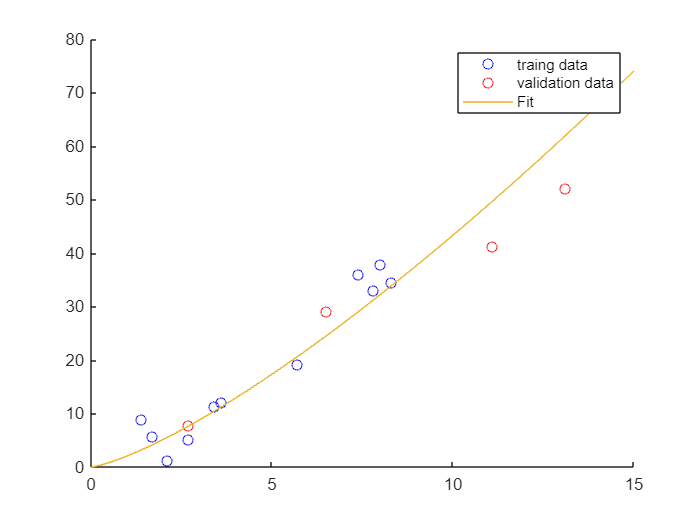


figure;
scatter(x, y, 'b'); 

hold on;
scatter(xv, yv, 'r'); 

c = 0:0.1:15;
f = k1 * c.^k2;
plot(c,f);
legend('traing data' , 'validation data','Fit')



poly_orders = 1:4;
SSE_poly = zeros(size(poly_orders));

for i = 1:length(poly_orders)
    p = polyfit(x, y, poly_orders(i));
    f = polyval(p, xv);
    SSE_poly(i) = sum((yv - f).^2);
    fprintf('SSE for polynomial order %d: %f\n', poly_orders(i), SSE_poly(i));
end

SSE for polynomial order 1: 145.425856
SSE for polynomial order 2: 1880.078804
SSE for polynomial order 3: 4737.329378
SSE for polynomial order 4: 436.903369



% 选择最佳多项式阶数
[min_SSE, best_order] = min(SSE_poly);
fprintf('Best polynomial order %d，whose SSE 为 %f\n', poly_orders(best_order), min_SSE);

Best polynomial order 1，whose SSE 为 145.425856


%---------------------------------------------------------------

# **Problem 4 (2.5 points)**

**The task is to estimate the parameters **${\mathit{\mathbf{k}}}_{\mathit{\mathbf{i}}}$** of the following nonlinear function:**

## 
$$z=k_1 \left(1-e^{k_2 t} \right)$$


- **Load the datafile: **In the script below, load the “data4.mat” datafile. The file contains inputs **t** and outputs **z**.

- **Implement least squares: **Implement a cost function "computeCost.m" in a different script to calculate the Sum of Squared Errors (SSE) between the data points and the fitted function. The cost function takes the parameters $\mathit{\mathbf{k}}$ as an input and returns the value of SSE as an output. **(1 point)**

- **Estimate: **Estimate the parameters, ${\mathit{\mathbf{k}}}_1$ and ${\mathit{\mathbf{k}}}_2$, of the above stated function by minimizing the "computeCost" using the function [**fminsearch**](https://se.mathworks.com/help/matlab/ref/fminsearch.html) and the provided data. Initialize the search with the following values: ${\mathit{\mathbf{k}}}_1 =1$ and ${\mathit{\mathbf{k}}}_2 =1$. **(0.75 points)**

- **Visualize** the cost function near its global minimum.** Hint:** Use the [**surf**](https://se.mathworks.com/help/matlab/ref/surf.html) function to do so. **(0.75 points)**

clear

load('data4.mat'); % Load the datafile

global t z % Declare the variables as global to enable computeCost access them

%---------------------------------------------------------------

initial_params = [1, 1];
fun = @(params)computeCost(params,t,z);
optimal_k = fminsearch(fun, initial_params);

k1 = optimal_k(1);
k2 = optimal_k(2);

fprintf('Estimated k1: %.4f\n', k1);

Estimated k1: 1.4927


fprintf('Estimated k2: %.4f\n', k2);

Estimated k2: -0.2021


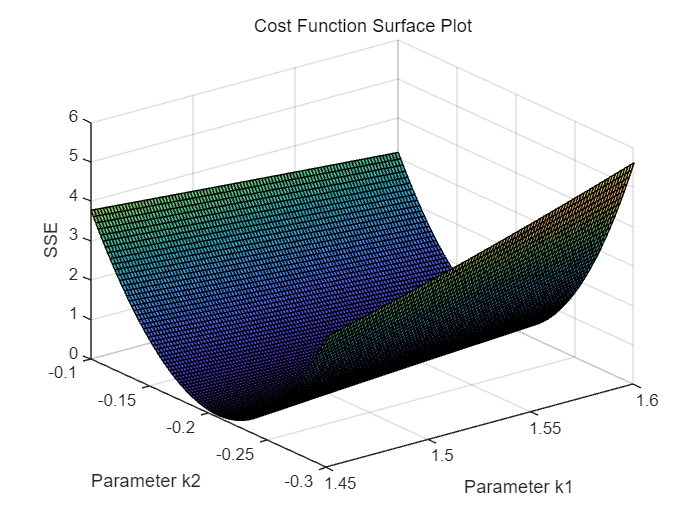

% Create a grid of parameter values to visualize the cost function
k1_values = linspace(1.45, 1.6, 100); % Define the range for k1
k2_values = linspace(-0.1, -0.3, 100); % Define the range for k2

% Create a surface plot of the cost function
[K1, K2] = meshgrid(k1_values, k2_values);

% Create empty matrices to store SSE values and parameter combinations

% Loop through k1 and k2 values to calculate SSE
for i = 1:length(k1_values)
    for j = 1:length(k2_values)
        SSE_values(j, i) = computeCost([k1_values(i), k2_values(j)], t, z);
    end
end

figure;
surf(K1,K2,SSE_values);

xlabel('Parameter k1');
ylabel('Parameter k2');
zlabel('SSE');
title('Cost Function Surface Plot');



%---------------------------------------------------------------


# **What to return?**

You are expected to submit your assignment to the related link for Assignment 3 in MyCourses.

Your submission should include:

- One completed .mlx file: **Assignment_3_*your_student_number*.mlx**

- MATLAB script:** createFit1.m **(optional)

- MATLAB script:** createFit2.m**

- MATLAB script:** computeCost.m**